# **The Effects of Social Gathering Size on Disease Spread**

Bertrand Aristide Inshuti, Derek Martielli

## Question

### How does limiting the size of social gatherings affect the rate of disease spread in a population? 

This question is more general as we are aiming to find trends instead of specific values. The question is also more rhetorical as we are not in direct control of limiting the sizes of social gatherings. The motivation for this question comes from the experience of COVID-19. During the peak of the virus many governments set limits on sizes for social gatherings. While this was far from the only measure implemented, it would be interesting to see how it may have helped lessen the spread.

#### Research Synthesis Matrix

A lot of the research we found assumed a distribution of group sizes and looked at the impact of each group size. While this doesn't answer our question it does give guidance on how we might make and validate our model. We found that the use of extra parameters beyond SIR was not necessary, and that we can expect lower person mobility to reduce disease spread.

## **Methodology/Model**

To investigate how the limiting size of social gatherings limits the spread of disease, we built an agent-based SIR model (ABSIR). 

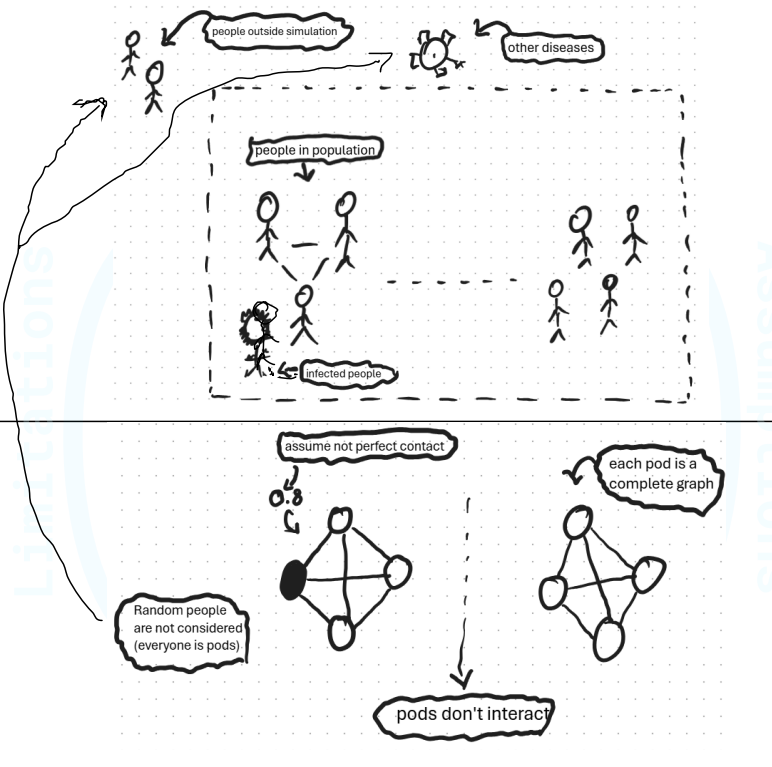

Each agent could be susceptible, infected, or recovered. Interactions happen person-to-person in structured “pods” that represent social gatherings of fixed sizes. The people in each pod change every time step and agents don't always go to social gathering.

Here is the general overview of one simulation step:

- Agents who choose not to gather get temporarily removed from the dataset

- The remaining agents are randomly put into pods

- The infection simulation is run

- The data is merged back together

- All agents that are elibible to recover check to see if they do recover

There are a few assumptions and limitations worth noting.

- The social gathering "pods" are complete. In reality people may not have complete and equal contact with everyone at a social gathering. By having complete pods we assume a worst case scenario. We can still see the effects pods have though even with this limitation.

- The pods are fully isolated from eachother. While there may normally be some interaction between pods, we are assuming a quarantive-like situation where there are limited group sizes and interactions between people.

- The pods are all (mostly) the same size. As mentioned above, a lot of papers run models where there is a distribution of pod sizes each step. The pods in our model are all the same size (except for one overflow pod when the population is not divisible by the pod size). Although our method isn't completly accurate, we can still get data on how the different social gathering sizes affect disease spread.

- The agents are randomly put into pods. In the real world people are more likely to group with some people more often. Again, this is like assuming the worst case scenario where agents are constantly grouped with random people. The data can still offer insights about the effects of groups even when assuming the worst conditions.

Detailed model breakdown:

The whole model takes 7 input variables and outputs 3 variables.

The function $\textrm{simulate}\_\textrm{absir}\left(\right)$ is responsible for formating these inputs and looping the $\textrm{action}\left(\right)$ function. For more details see [simulate_absir.m](https://github.com/derek-forgot/ModSim-Project2/blob/main/simulate_absir.m)

The first step of the action function is to remove an amount of the population proportional to the gathering chance.

Next $\mathrm{I}$ and $\mathrm{R}$ get scrambled. Note that the order is stored so that it may be unscrambled later

A function is then run to make a social graph that puts agents into pods.

If the population is not divisible by the pod size the function will make the last pod smaller. For more details see [pod_maker.m](https://github.com/derek-forgot/ModSim-Project2/blob/main/pod_maker.m)

plot(graph(pod_maker(11,4))); title("Example Graph With 11 People and Pod Size of 4");

The social graph is used to compute infection probabilities

Random values are drawn using this data for who gets infected and recovered. They are not yet applied to the data as there needs to be update rules. Also note that $\mathrm{v}\_\textrm{recover}$ is generated for the whole population as people who didnt gather could still recover.

The infected list is updated with the following rule: an agent is infected IF they are currently infected OR just got infected AND are not recovered. The list of people that become infected is stored so that they dont recover in the same step.

Next the lists are unscrambled.

The newly updated data is merged back together with the stuff removed in the first step.

Finally, the recovery step is applied. An agent is recovered IF they are currently recovered OR they are infected AND recovered AND not just infected. The infected list is updated to remove people who are recovered.

Now that the function is defined we can do some verification to see that it works!

First we will check that all of the states always add up to the population. The exact numbers here don't matter but there will be a population of 100 people for 100 timesteps.

[Sh,Ih,Rh] = simulate_absir(100,(rand(100,1)<0.1),100,0.4,0.1,5,0.6);   %Run the simulation
working = sum(Sh,1) + sum(Ih,1) + sum(Rh,1);  %Sum susceptible, infected, and recovered per timestep
plot(working); title("Total Population Over Time (Should be Flat)"); xlabel("Simulation Timestep");ylabel("Total Population");    %Graph the results
assert(all(working == working(1))); disp("Assertion passed, the population is the same at all timesteps");

Assertion passed, the population is the same at all timesteps


Hooray! The population stays steady. Now we can check to see if people who become recovered stay recovered for the rest of the similation. This will be done through graphing the recovery and checking that the recovery population never goes down.

spy(Rh,"_"); title("Recovered History"); xlabel("Timestep"); ylabel("Person by Number"); pbaspect([3 2 1]);

Figure X. Full recovery history from example run.

assert(all(diff(sum(Rh,1))>=0));disp("Assertion passed, the recovered population never decreases")

Assertion passed, the recovered population never decreases


Some people take a while before becoming recovered but nobody every becomes un-recovered. This plot also confirms that the scramble and unscramble are functioning correctly as each agents keeps the same number. 

We can now do some validation with the research found earlier. The things to validate are:

- Smaller gathering sites generally produce lower and later infection peaks (Christopher B. Boyer et al.)

- Very large gatherings should lead to a higher rate of infections (Chuwei Liu et al.)

- Reducing mobility (chance of gathering) should decrease transmission with consistent gathering sizes (Lanxin Zhang, Peter Taylor)

To compare our models results we need to decide on base parameters. The population count and timesteps are somewhat arbitrary. We will simulate 200 people for 100 timesteps. The infection rate is set to 0.4. This means that an infected person has a 40% chance of infecting a susceptible person. The recovery rate is put at 0.1 so that on average, it will take 10 days to recover. The chance of gathering is set to a reasonable 60%. We will initialize the simulation with 10% of the population infected. The model will be run 100 times and averaged to help filter out randomness.

%Demo Variables
population = 200;
pod_size = 4;
time_steps = 100;
infection_rate = 0.4;
recovery_rate = 0.1;
gathering_chance = 0.6;
Iv0 = rand(population,1)<0.1;

%Run the simulation 100 times and average
for run=1:100
[~,Ih,~] = simulate_absir(population,Iv0, time_steps, infection_rate, recovery_rate,pod_size,gathering_chance);
I_count(run,:) = sum(Ih, 1);
end
I_count = mean(I_count,1);

%Plot
plot(I_count); title("Demo Run"); xlabel("Day");ylabel("Amount of People Infected");

To analyze how gathering size influences spread, we performed a parameter sweep varying pod sizes from 2 to 10. For each pod size, we re-ran the model and recorded the total number of infected individuals over time. Comparing these infection curves showed that larger gatherings amplify transmission, while smaller pods slow the epidemic. This approach enabled a controlled, systematic evaluation of how social-group size constraints shape outbreak dynamics.

%Demo Sweep
I_count_sweep = [];
for i=2:10
  [~,Ih,~] = simulate_absir(population,Iv0, time_steps, infection_rate, recovery_rate,i,gathering_chance);
  I_count_sweep(:,i-1) = sum(Ih, 1).';
end
plot(I_count_sweep)

MORE VALIDATION HERE

## Result

In all simulations we ran, we observed that larger gatherings led to significantly higher, faster infection peaks, while smaller pods had lower, slower infection peaks. When the pods were smaller, like 2-4 people, the infection curve rose gradually and peaked at a much lower level, showing that limiting gatherings effectively suppressed transmission. As pod sizes increased to 6-10 people, infections grew rapidly, producing earlier and much higher peaks. The sweep demonstrated that gathering size is the main amplifier of disease spread, with even moderate increases in group size causing substantial increases in total infections over time.

## **Interpretation**

  Our results suggest that the size of social gatherings has a decisive role in shaping how quickly and widely a disease spreads. When the gatherings were kept small, infections went up slowly but never actually reached the same magnitude, which indicates that limiting group size effectively interrupts transmission chains. However, larger gatherings led to a greater mixture of both infected and susceptible, which caused the epidemic to accelerate and peak at much higher levels. Overall, the model implies that policies restricting gathering sizes can substantially reduce both the speed and total scale of an outbreak, making this one of the most impactful and straightforward interventions for controlling disease spread. 

## AI Statement:

  AI was not used during this project.